%% Example Usage of Suspension Kinematics Solver
% This script shows how to use the suspensionKinematics function
% with your existing naming convention

clear; clc; close all;

%% Define shim offsets (from your code)
clevisOriginOffset = [0, 0, 0];  % Define if needed
nominalCamberShim = [0, 6.6, 0];
clevisShimOffsetUFA = [0, 9, 0];
clevisShimOffsetUAA = [0, 9, 0];
clevisShimOffsetLFA = [0, 9, 0];
clevisShimOffsetLAA = [0, 9, 0];

uprightConnector = [0, 82.5, 0];

%% Define pickup points (matching your naming convention)
% Upper A-Arm
vehicle.rear.upperAArm.fore = [530.5, 417, 296] + clevisOriginOffset + clevisShimOffsetUFA;
vehicle.rear.upperAArm.aft = [830.5, 417, 296] + clevisOriginOffset + clevisShimOffsetUAA;
vehicle.rear.upperAArm.ballJoint = [680.5, 688.658, 325.3967] + uprightConnector + nominalCamberShim;

% Lower A-Arm
vehicle.rear.lowerAArm.fore = [470.5, 244, 71] + clevisOriginOffset + clevisShimOffsetLFA;
vehicle.rear.lowerAArm.aft = [925.5, 244, 71] + clevisOriginOffset + clevisShimOffsetLAA;
vehicle.rear.lowerAArm.ballJoint = [810.9965, 801.4376, 42.009];

% Toe Rod
vehicle.rear.toeRod.upright = [810.9965, 801.9947, 43.6768];
vehicle.rear.toeRod.chassis = [911.6355, 384.1572, 65.5999];

% Contact Patch (example - adjust to your actual value)
% Typically directly below wheel center at ground level
vehicle.rear.contactPatch = [696, 800, -128.17];  % Adjust Y to your track width, Z=0 at ground

%% Create params struct for the solver
params.upperAArm.fore = vehicle.rear.upperAArm.fore;
params.upperAArm.aft = vehicle.rear.upperAArm.aft;
params.upperAArm.ballJoint = vehicle.rear.upperAArm.ballJoint;
params.lowerAArm.fore = vehicle.rear.lowerAArm.fore;
params.lowerAArm.aft = vehicle.rear.lowerAArm.aft;
params.lowerAArm.ballJoint = vehicle.rear.lowerAArm.ballJoint;
params.toeRod.chassis = vehicle.rear.toeRod.chassis;
params.toeRod.upright = vehicle.rear.toeRod.upright;
params.contactPatch = vehicle.rear.contactPatch;

%% Define wheel travel range
wheelTravel = linspace(-40, 40, 81);  % -50mm to +50mm, 101 points

%% Run the solver
results = suspensionKinematics(params, wheelTravel);

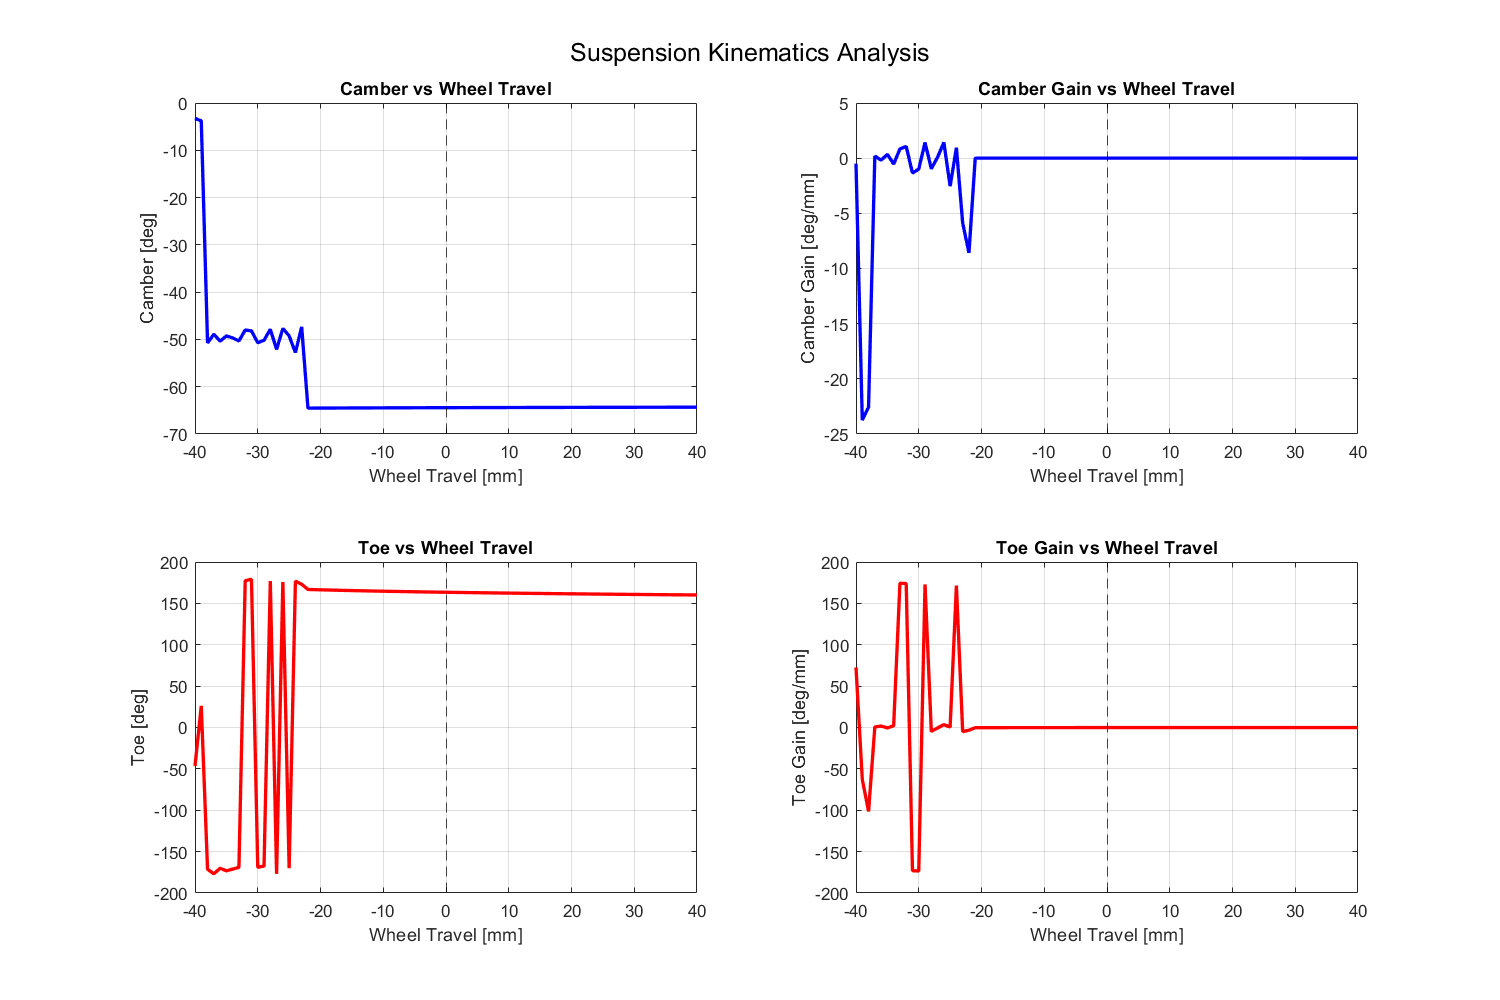


%% Plot Results
figure('Position', [100, 100, 1200, 800]);

% Camber vs Wheel Travel
subplot(2,2,1);
plot(results.wheelTravel, results.camber, 'b-', 'LineWidth', 2);
grid on;
xlabel('Wheel Travel [mm]');
ylabel('Camber [deg]');
title('Camber vs Wheel Travel');
xline(0, '--k');

% Camber Gain vs Wheel Travel
subplot(2,2,2);
plot(results.wheelTravel, results.camberGain, 'b-', 'LineWidth', 2);
grid on;
xlabel('Wheel Travel [mm]');
ylabel('Camber Gain [deg/mm]');
title('Camber Gain vs Wheel Travel');
xline(0, '--k');

% Toe vs Wheel Travel
subplot(2,2,3);
plot(results.wheelTravel, results.toe, 'r-', 'LineWidth', 2);
grid on;
xlabel('Wheel Travel [mm]');
ylabel('Toe [deg]');
title('Toe vs Wheel Travel');
xline(0, '--k');

% Toe Gain vs Wheel Travel
subplot(2,2,4);
plot(results.wheelTravel, results.toeGain, 'r-', 'LineWidth', 2);
grid on;
xlabel('Wheel Travel [mm]');
ylabel('Toe Gain [deg/mm]');
title('Toe Gain vs Wheel Travel');
xline(0, '--k');

sgtitle('Suspension Kinematics Analysis');


%% Print key values at ride height
[~, idx_ride] = min(abs(results.wheelTravel));
fprintf('\n=== Values at Ride Height ===\n');


=== Values at Ride Height ===


fprintf('Camber: %.3f deg\n', results.camber(idx_ride));

Camber: -64.433 deg


fprintf('Camber Gain: %.4f deg/mm\n', results.camberGain(idx_ride));

Camber Gain: 0.0036 deg/mm


fprintf('Toe: %.3f deg\n', results.toe(idx_ride));

Toe: 163.421 deg


fprintf('Toe Gain: %.4f deg/mm\n', results.toeGain(idx_ride));

Toe Gain: -0.1123 deg/mm



%% Print values at bump and droop
[~, idx_bump] = min(abs(results.wheelTravel - 25));
[~, idx_droop] = min(abs(results.wheelTravel + 25));

fprintf('\n=== Values at 25mm Bump ===\n');


=== Values at 25mm Bump ===


fprintf('Camber: %.3f deg\n', results.camber(idx_bump));

Camber: -64.359 deg


fprintf('Camber Gain: %.4f deg/mm\n', results.camberGain(idx_bump));

Camber Gain: 0.0023 deg/mm


fprintf('Toe: %.3f deg\n', results.toe(idx_bump));

Toe: 161.169 deg


fprintf('Toe Gain: %.4f deg/mm\n', results.toeGain(idx_bump));

Toe Gain: -0.0740 deg/mm



fprintf('\n=== Values at 25mm Droop ===\n');


=== Values at 25mm Droop ===


fprintf('Camber: %.3f deg\n', results.camber(idx_droop));

Camber: -49.247 deg


fprintf('Camber Gain: %.4f deg/mm\n', results.camberGain(idx_droop));

Camber Gain: -2.5387 deg/mm


fprintf('Toe: %.3f deg\n', results.toe(idx_droop));

Toe: -169.969 deg


fprintf('Toe Gain: %.4f deg/mm\n', results.toeGain(idx_droop));

Toe Gain: 0.5114 deg/mm


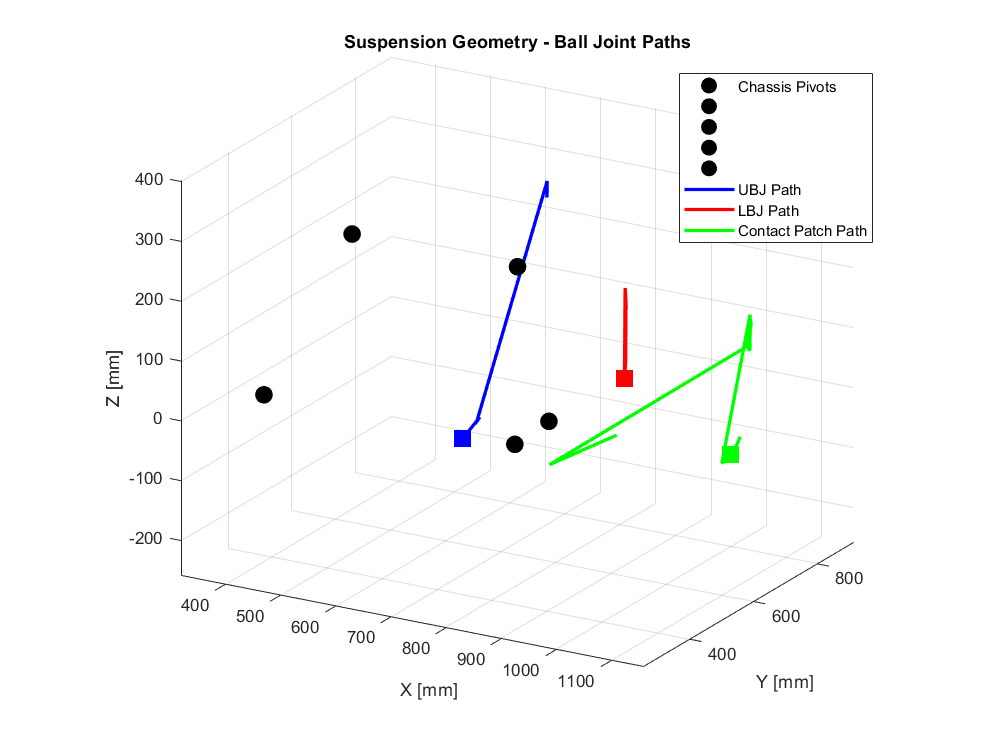


%% 3D Visualization of Suspension Movement
figure('Position', [100, 100, 800, 600]);
hold on; grid on; axis equal;
view(30, 20);

% Plot chassis pivots (fixed)
plot3(params.upperAArm.fore(1), params.upperAArm.fore(2), params.upperAArm.fore(3), 'ko', 'MarkerSize', 10, 'MarkerFaceColor', 'k');
plot3(params.upperAArm.aft(1), params.upperAArm.aft(2), params.upperAArm.aft(3), 'ko', 'MarkerSize', 10, 'MarkerFaceColor', 'k');
plot3(params.lowerAArm.fore(1), params.lowerAArm.fore(2), params.lowerAArm.fore(3), 'ko', 'MarkerSize', 10, 'MarkerFaceColor', 'k');
plot3(params.lowerAArm.aft(1), params.lowerAArm.aft(2), params.lowerAArm.aft(3), 'ko', 'MarkerSize', 10, 'MarkerFaceColor', 'k');
plot3(params.toeRod.chassis(1), params.toeRod.chassis(2), params.toeRod.chassis(3), 'ko', 'MarkerSize', 10, 'MarkerFaceColor', 'k');

% Plot ball joint paths
plot3(results.upperBallJoint(:,1), results.upperBallJoint(:,2), results.upperBallJoint(:,3), 'b-', 'LineWidth', 2);
plot3(results.lowerBallJoint(:,1), results.lowerBallJoint(:,2), results.lowerBallJoint(:,3), 'r-', 'LineWidth', 2);
plot3(results.contactPatch(:,1), results.contactPatch(:,2), results.contactPatch(:,3), 'g-', 'LineWidth', 2);

% Plot ride height position
plot3(results.upperBallJoint(idx_ride,1), results.upperBallJoint(idx_ride,2), results.upperBallJoint(idx_ride,3), 'bs', 'MarkerSize', 12, 'MarkerFaceColor', 'b');
plot3(results.lowerBallJoint(idx_ride,1), results.lowerBallJoint(idx_ride,2), results.lowerBallJoint(idx_ride,3), 'rs', 'MarkerSize', 12, 'MarkerFaceColor', 'r');
plot3(results.contactPatch(idx_ride,1), results.contactPatch(idx_ride,2), results.contactPatch(idx_ride,3), 'gs', 'MarkerSize', 12, 'MarkerFaceColor', 'g');

xlabel('X [mm]');
ylabel('Y [mm]');
zlabel('Z [mm]');
title('Suspension Geometry - Ball Joint Paths');
legend('Chassis Pivots', '', '', '', '', 'UBJ Path', 'LBJ Path', 'Contact Patch Path', 'Location', 'best');

function [results] = suspensionKinematics(params, wheelTravel)
% SUSPENSIONKINEMATICS Solves double wishbone suspension kinematics
%
% Inputs:
%   params - struct containing all pickup points (x,y,z coordinates)
%   wheelTravel - array of vertical displacements at contact patch [mm]
%
% Outputs:
%   results - struct containing:
%       .wheelTravel - input wheel travel [mm]
%       .camber - camber angle [deg]
%       .camberGain - d(camber)/dz [deg/mm]
%       .toe - toe angle [deg]
%       .toeGain - d(toe)/dz [deg/mm]
%       .contactPatch - contact patch positions [x,y,z]
%       .upperBallJoint - UBJ positions [x,y,z]
%       .lowerBallJoint - LBJ positions [x,y,z]

%% Extract pickup points from params
P_UF = params.upperAArm.fore(:);       % Upper A-arm fore chassis pivot
P_UA = params.upperAArm.aft(:);        % Upper A-arm aft chassis pivot
P_UBJ0 = params.upperAArm.ballJoint(:); % Upper ball joint initial
P_LF = params.lowerAArm.fore(:);       % Lower A-arm fore chassis pivot
P_LA = params.lowerAArm.aft(:);        % Lower A-arm aft chassis pivot
P_LBJ0 = params.lowerAArm.ballJoint(:); % Lower ball joint initial
P_TC = params.toeRod.chassis(:);       % Toe rod chassis pivot
P_TU0 = params.toeRod.upright(:);      % Toe rod upright pivot initial
P_CP0 = params.contactPatch(:);        % Contact patch initial

%% Calculate fixed link lengths
L_UF = norm(P_UBJ0 - P_UF);
L_UA = norm(P_UBJ0 - P_UA);
L_LF = norm(P_LBJ0 - P_LF);
L_LA = norm(P_LBJ0 - P_LA);
L_TR = norm(P_TU0 - P_TC);
L_upright = norm(P_UBJ0 - P_LBJ0);

%% Calculate circle parameters for lower A-arm
[P_circleL, r_L, u_L, v_L] = calculateCircleParams(P_LF, P_LA, L_LF, L_LA);

%% Calculate circle parameters for upper A-arm
[P_circleU, r_U, u_U, v_U] = calculateCircleParams(P_UF, P_UA, L_UF, L_UA);

%% Calculate initial angles
theta_L0 = findInitialAngle(P_LBJ0, P_circleL, r_L, u_L, v_L);
theta_U0 = findInitialAngle(P_UBJ0, P_circleU, r_U, u_U, v_U);

%% Calculate initial upright orientation
w0 = P_UBJ0 - P_LBJ0;
w0_hat = w0 / norm(w0);

% Toe rod offset in initial upright frame
r_TU0 = P_TU0 - P_LBJ0;

% Contact patch offset from LBJ in initial frame
r_CP0 = P_CP0 - P_LBJ0;

% Initial wheel forward direction (perpendicular to KPI, in X-Y plane)
f0 = [1; 0; 0];
f0 = f0 - dot(f0, w0_hat) * w0_hat;  % Make perpendicular to KPI
f0 = f0 / norm(f0);

% Initial lateral direction (completes right-hand frame)
lat0 = cross(w0_hat, f0);
lat0 = lat0 / norm(lat0);

%% Store geometry for nested functions
geom.P_circleL = P_circleL;
geom.P_circleU = P_circleU;
geom.r_L = r_L;
geom.r_U = r_U;
geom.u_L = u_L;
geom.v_L = v_L;
geom.u_U = u_U;
geom.v_U = v_U;
geom.L_upright = L_upright;
geom.L_TR = L_TR;
geom.P_TC = P_TC;
geom.r_TU0 = r_TU0;
geom.r_CP0 = r_CP0;
geom.w0_hat = w0_hat;
geom.f0 = f0;
geom.lat0 = lat0;
geom.P_CP0 = P_CP0;

%% Preallocate results
nPoints = length(wheelTravel);
camber = zeros(nPoints, 1);
toe = zeros(nPoints, 1);
contactPatch = zeros(nPoints, 3);
upperBallJoint = zeros(nPoints, 3);
lowerBallJoint = zeros(nPoints, 3);

%% Solver settings
maxIter = 50;
tol = 1e-10;

%% Solve for each wheel travel position
x = [theta_L0; theta_U0; 0];  % Initial guess [theta_L, theta_U, phi]

for i = 1:nPoints
    dz = wheelTravel(i);
    
    % Newton-Raphson iteration
    for iter = 1:maxIter
        [F, J] = constraintEquationsWithJacobian(x, dz, geom);
        
        if norm(F) < tol
            break;
        end
        
        % Solve for update
        dx = J \ (-F);
        x = x + dx;
        
        if norm(dx) < tol
            break;
        end
    end
    
    if iter == maxIter && norm(F) > tol
        warning('Newton-Raphson did not converge for wheelTravel = %.2f mm (residual = %.2e)', dz, norm(F));
    end
    
    theta_L = x(1);
    theta_U = x(2);
    phi = x(3);
    
    % Calculate positions
    P_LBJ = geom.P_circleL + geom.r_L * (cos(theta_L) * geom.u_L + sin(theta_L) * geom.v_L);
    P_UBJ = geom.P_circleU + geom.r_U * (cos(theta_U) * geom.u_U + sin(theta_U) * geom.v_U);
    
    % Current KPI axis
    w = P_UBJ - P_LBJ;
    w_hat = w / norm(w);
    
    % Rotation matrix from initial to current upright orientation
    R_kpi = rotationBetweenVectors(geom.w0_hat, w_hat);
    
    % Additional rotation about KPI axis (toe)
    R_toe = axisAngleRotation(w_hat, phi);
    
    % Total rotation
    R_total = R_toe * R_kpi;
    
    % Contact patch position
    r_CP = R_total * geom.r_CP0;
    P_CP = P_LBJ + r_CP;
    
    % Calculate camber (angle of KPI projected onto Y-Z plane)
    camber(i) = asind(w_hat(2));
    
    % Calculate toe (wheel pointing direction projected onto X-Y plane)
    f_current = R_total * geom.f0;
    toe(i) = atan2d(f_current(2), f_current(1));
    
    % Store positions
    contactPatch(i,:) = P_CP';
    upperBallJoint(i,:) = P_UBJ';
    lowerBallJoint(i,:) = P_LBJ';
end

%% Calculate gains (numerical differentiation)
camberGain = gradient(camber, wheelTravel);
toeGain = gradient(toe, wheelTravel);

%% Package results
results.wheelTravel = wheelTravel(:);
results.camber = camber;
results.camberGain = camberGain;
results.toe = toe;
results.toeGain = toeGain;
results.contactPatch = contactPatch;
results.upperBallJoint = upperBallJoint;
results.lowerBallJoint = lowerBallJoint;

end

%% Helper Functions

function [P_circle, r, u, v] = calculateCircleParams(P1, P2, L1, L2)
% Calculate the circle of intersection between two spheres
% Sphere 1: center P1, radius L1
% Sphere 2: center P2, radius L2

d_vec = P2 - P1;
d = norm(d_vec);
d_hat = d_vec / d;

% Distance from P1 to circle center along d_hat
a = (L1^2 - L2^2 + d^2) / (2*d);

% Circle center
P_circle = P1 + a * d_hat;

% Circle radius
r = sqrt(L1^2 - a^2);

% Orthonormal basis perpendicular to d_hat
k = [0; 0; 1];
if abs(dot(d_hat, k)) > 0.99
    k = [1; 0; 0];
end

u = cross(d_hat, k);
u = u / norm(u);
v = cross(d_hat, u);
v = v / norm(v);

end

function theta = findInitialAngle(P, P_circle, r, u, v)
% Find the angle that gives point P on the circle
offset = P - P_circle;
cos_theta = dot(offset, u) / r;
sin_theta = dot(offset, v) / r;
theta = atan2(sin_theta, cos_theta);
end

function [F, J] = constraintEquationsWithJacobian(x, dz, geom)
% System of constraint equations with analytical Jacobian
% x = [theta_L, theta_U, phi]
% dz = prescribed wheel travel (contact patch z displacement)

theta_L = x(1);
theta_U = x(2);
phi = x(3);

% Precompute trig functions
cL = cos(theta_L); sL = sin(theta_L);
cU = cos(theta_U); sU = sin(theta_U);
cP = cos(phi); sP = sin(phi);

% Ball joint positions
P_LBJ = geom.P_circleL + geom.r_L * (cL * geom.u_L + sL * geom.v_L);
P_UBJ = geom.P_circleU + geom.r_U * (cU * geom.u_U + sU * geom.v_U);

% Derivatives of ball joint positions
dP_LBJ_dthL = geom.r_L * (-sL * geom.u_L + cL * geom.v_L);
dP_UBJ_dthU = geom.r_U * (-sU * geom.u_U + cU * geom.v_U);

% Upright vector
w = P_UBJ - P_LBJ;
w_norm = norm(w);
w_hat = w / w_norm;

% Constraint 1: Upright length squared
F1 = w_norm^2 - geom.L_upright^2;

% Jacobian of F1
dF1_dthL = 2 * dot(w, -dP_LBJ_dthL);
dF1_dthU = 2 * dot(w, dP_UBJ_dthU);
dF1_dphi = 0;

% Rotation from initial to current KPI orientation
R_kpi = rotationBetweenVectors(geom.w0_hat, w_hat);

% Rotation about current KPI axis
R_toe = axisAngleRotation(w_hat, phi);

% Total rotation
R_total = R_toe * R_kpi;

% Toe rod upright pickup position
r_TU = R_total * geom.r_TU0;
P_TU = P_LBJ + r_TU;

% Toe rod vector
TR_vec = P_TU - geom.P_TC;

% Constraint 2: Toe rod length squared
F2 = dot(TR_vec, TR_vec) - geom.L_TR^2;

% Contact patch position
r_CP = R_total * geom.r_CP0;
P_CP = P_LBJ + r_CP;

% Constraint 3: Contact patch Z position
F3 = P_CP(3) - (geom.P_CP0(3) + dz);

% Numerical Jacobian for F2 and F3 (rotation derivatives are complex)
delta = 1e-8;

% Perturb theta_L
x_pert = x + [delta; 0; 0];
[F_pert, ~] = constraintEquationsNoJac(x_pert, dz, geom);
dF2_dthL = (F_pert(2) - F2) / delta;
dF3_dthL = (F_pert(3) - F3) / delta;

% Perturb theta_U
x_pert = x + [0; delta; 0];
[F_pert, ~] = constraintEquationsNoJac(x_pert, dz, geom);
dF2_dthU = (F_pert(2) - F2) / delta;
dF3_dthU = (F_pert(3) - F3) / delta;

% Perturb phi
x_pert = x + [0; 0; delta];
[F_pert, ~] = constraintEquationsNoJac(x_pert, dz, geom);
dF2_dphi = (F_pert(2) - F2) / delta;
dF3_dphi = (F_pert(3) - F3) / delta;

F = [F1; F2; F3];

J = [dF1_dthL, dF1_dthU, dF1_dphi;
     dF2_dthL, dF2_dthU, dF2_dphi;
     dF3_dthL, dF3_dthU, dF3_dphi];

end

function [F, dummy] = constraintEquationsNoJac(x, dz, geom)
% Constraint equations without Jacobian (for numerical differentiation)

theta_L = x(1);
theta_U = x(2);
phi = x(3);

% Ball joint positions
P_LBJ = geom.P_circleL + geom.r_L * (cos(theta_L) * geom.u_L + sin(theta_L) * geom.v_L);
P_UBJ = geom.P_circleU + geom.r_U * (cos(theta_U) * geom.u_U + sin(theta_U) * geom.v_U);

% Upright vector
w = P_UBJ - P_LBJ;
w_norm = norm(w);
w_hat = w / w_norm;

% Constraint 1: Upright length squared
F1 = w_norm^2 - geom.L_upright^2;

% Rotations
R_kpi = rotationBetweenVectors(geom.w0_hat, w_hat);
R_toe = axisAngleRotation(w_hat, phi);
R_total = R_toe * R_kpi;

% Toe rod constraint
r_TU = R_total * geom.r_TU0;
P_TU = P_LBJ + r_TU;
TR_vec = P_TU - geom.P_TC;
F2 = dot(TR_vec, TR_vec) - geom.L_TR^2;

% Contact patch constraint
r_CP = R_total * geom.r_CP0;
P_CP = P_LBJ + r_CP;
F3 = P_CP(3) - (geom.P_CP0(3) + dz);

F = [F1; F2; F3];
dummy = [];

end

function R = rotationBetweenVectors(a, b)
% Rotation matrix that rotates unit vector a to unit vector b
% Using Rodrigues' rotation formula

a = a / norm(a);
b = b / norm(b);

v = cross(a, b);
s = norm(v);
c = dot(a, b);

if s < 1e-10
    if c > 0
        R = eye(3);
    else
        % 180 degree rotation - find perpendicular axis
        if abs(a(1)) < 0.9
            perp = cross(a, [1;0;0]);
        else
            perp = cross(a, [0;1;0]);
        end
        perp = perp / norm(perp);
        R = axisAngleRotation(perp, pi);
    end
    return;
end

vx = [0, -v(3), v(2);
      v(3), 0, -v(1);
     -v(2), v(1), 0];

R = eye(3) + vx + vx*vx * (1-c)/(s^2);

end

function R = axisAngleRotation(axis, angle)
% Rotation matrix for rotation about axis by angle (radians)
% Using Rodrigues' formula

axis = axis / norm(axis);
K = [0, -axis(3), axis(2);
     axis(3), 0, -axis(1);
    -axis(2), axis(1), 0];

R = eye(3) + sin(angle)*K + (1-cos(angle))*K*K;

end

function F = constraintEquations(x, dz, geom)
% System of constraint equations
% x = [theta_L, theta_U, phi]
% dz = prescribed wheel travel (contact patch z displacement)

theta_L = x(1);
theta_U = x(2);
phi = x(3);

% Ball joint positions
P_LBJ = geom.P_circleL + geom.r_L * (cos(theta_L) * geom.u_L + sin(theta_L) * geom.v_L);
P_UBJ = geom.P_circleU + geom.r_U * (cos(theta_U) * geom.u_U + sin(theta_U) * geom.v_U);

% Constraint 1: Upright length
F1 = norm(P_UBJ - P_LBJ)^2 - geom.L_upright^2;

% Current KPI axis
w = P_UBJ - P_LBJ;
w_hat = w / norm(w);

% Rotation from initial to current upright orientation
R_kpi = rotationBetweenVectors(geom.w0_hat, w_hat);

% Additional rotation about KPI (toe rotation)
R_toe = axisAngleRotation(w_hat, phi);

% Total rotation
R_total = R_toe * R_kpi;

% Toe rod upright pickup position
r_TU = R_total * geom.r_TU0;
P_TU = P_LBJ + r_TU;

% Constraint 2: Toe rod length
F2 = norm(P_TU - geom.P_TC)^2 - geom.L_TR^2;

% Contact patch position
r_CP = R_total * geom.r_CP0;
P_CP = P_LBJ + r_CP;

% Constraint 3: Prescribed wheel travel
F3 = P_CP(3) - (geom.P_CP0(3) + dz);

F = [F1; F2; F3];

end

